Data collected.

clc
close all
clear all
startup();

Loading: C:\Users\Weilong Chen\OneDrive - Chalmers\Desktop\Sensor_Project\Sensorfusion smartphone\sensordata.jar


showIP();%If you use virtual machine, situation varies

Available network interfaces
    1.	192.168.1.106 (MediaTek Wi-Fi 6 MT7921 Wireless LAN Card)


********************
* SensorDataReader started on 192.168.1.106:3400
********************
Connection accepted from 192.168.1.101:48572


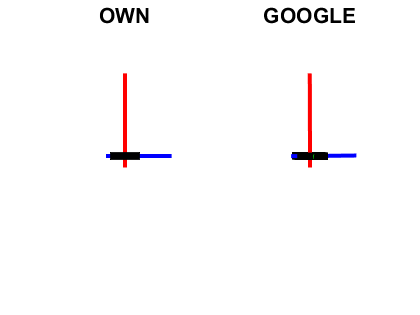

[xhat, meas] = filterTemplate();

Task1 see report.

TASK2

%using meas_static to calculate means and covirance for three sensors
clear all
load meas_static.mat
%mean
mu_acc = mean(meas.acc(:, ~any(isnan(meas.acc), 1)), 2);
mu_gyr = mean(meas.gyr(:, ~any(isnan(meas.gyr),1)), 2);
mu_mag = mean(meas.mag(:, ~any(isnan(meas.mag),1)), 2);
%covarience

R_acc = cov(meas.acc(:,~isnan(meas.acc(1,:)))');
R_gyr = cov(meas.gyr(:,~isnan(meas.gyr(1,:)))');
R_mag = cov(meas.mag(:,~isnan(meas.mag(1,:)))');


for i = 1:3
    p_acc(i) = cov(meas.acc(i,~any(isnan(meas.acc),1)));
    p_gyr(i) = cov(meas.gyr(i,~any(isnan(meas.gyr),1)));
    p_mag(i) = cov(meas.mag(i,~any(isnan(meas.mag),1)));
end
mean = [mu_acc mu_gyr mu_mag];
cov = [p_acc' p_gyr' p_mag'];
disp('Mean:');

Mean:


disp(mean);

    0.0665    0.0000    2.9769
    0.0866   -0.0000   18.4024
    9.9058   -0.0000  -40.5299



disp('Cov:');

Cov:


disp(cov);

    0.0000    0.0000    0.0953
    0.0000    0.0000    0.1026
    0.0001    0.0000    0.1097



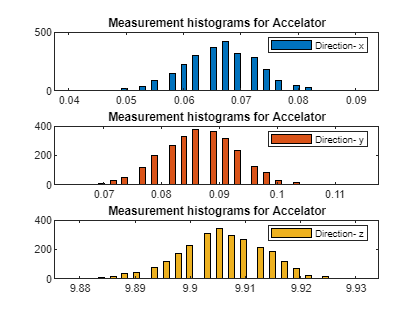

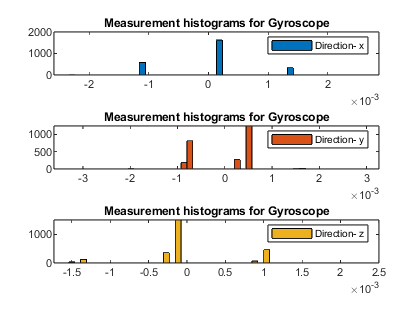

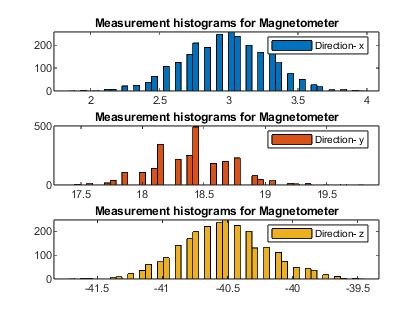

% Plot histograms with specified number of bins
bins = 50;

meas_set = {meas.acc, meas.gyr, meas.mag};
mu_set = {mu_acc, mu_gyr, mu_mag};
cov_set = {p_acc, p_gyr, p_mag};
sensor_set = {'Accelator', 'Gyroscope', 'Magnetometer'};
axes = ['x', 'y', 'z'];
color = colormap(lines);

for i = 1:3
    figure(i);    
    for j = 1:3
        subplot(3,1,j); 
        histogram(meas_set{i}(j,:), bins,'Normalization','count','FaceAlpha',1,'FaceColor',color(j,:));
        title(['Measurement histograms for ', sensor_set{i}]);
        legend(['Direction- ',axes(j)]);
    end
end

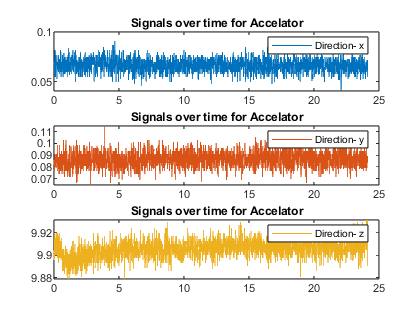

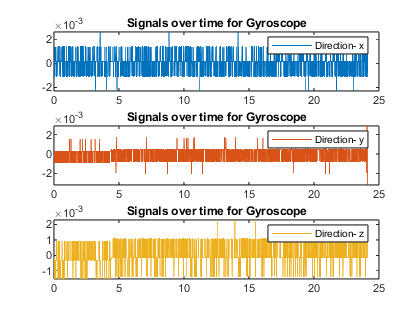

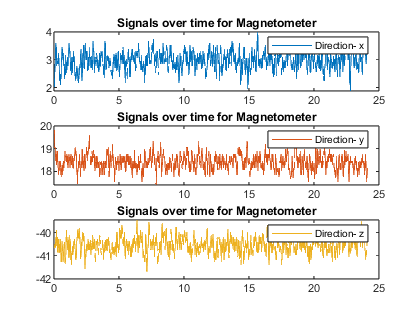


% signals over time  
figure;
for i = 1:3
    figure(i+3);
    for j = 1:3
        subplot(3,1,j); 
        plot(meas.t, meas_set{i}(j,:),'Color',color(j,:));
        title(['Signals over time for ', sensor_set{i}]);
        legend(['Direction- ',axes(j)]);
        
    end
end

Task3 see report for formula.

Task4 see tu_qw function and tu_qw_no function.

Task5

clc
close all
clear all
startup();

Loading: C:\Users\Weilong Chen\OneDrive - Chalmers\Desktop\Sensor_Project\Sensorfusion smartphone\sensordata.jar


showIP();%If you use virtual machine, situation varies

Available network interfaces
    1.	192.168.1.106 (MediaTek Wi-Fi 6 MT7921 Wireless LAN Card)


********************
* SensorDataReader started on 192.168.1.106:3400
********************
Connection accepted from 192.168.1.101:43760


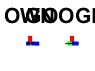

[xhat, meas] = filterTemplate_only_time_update();

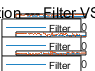

clc
close all
clear all
load meas_task5.mat
load xhat_task5.mat
%%  Plot the euler angles
filter = 180/pi*q2euler(xhat.x);
phone = 180/pi*q2euler(meas.orient);

figure;
sgtitle('Orientation --- Filter VS Phone')
subplot(3,1,1);
plot(xhat.t, filter(1,:))
hold on 
plot(meas.t, phone(1, :))
legend('Filter', 'Phone')
xlabel('time [s]')
ylabel('phi [deg]')

subplot(3,1,2);
plot(xhat.t, filter(2,:))
hold on 
plot(meas.t, phone(2, :))
legend('Filter', 'Phone')
xlabel('time [s]')
ylabel('theta [deg]')

subplot(3,1,3);
plot(xhat.t, filter(3,:))
hold on 
plot(meas.t, phone(3, :))
legend('Filter', 'Phone')
xlabel('time [s]')
ylabel('psi [deg]')

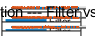

%change the tmin and tmax according to previous figure.
tmin = 0;
tmax = 12;
idx = xhat.t>tmin & xhat.t < tmax;

figure('Color','white','Position',[364   363  1258   473]);
sgtitle('Orientation --- Filter vs Phone')

subplot(3,1,1)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([1 0 0]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([1 0 0]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'phi [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})

subplot(3,1,2)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([0 1 0]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([0 1 0]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'theta [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})


subplot(3,1,3)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([0 0 1]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([0 0 1]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'psi [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})

Task6 see report

TASK7 acc_fusion

clc
close all
clear all
startup();

Loading: C:\Users\Weilong Chen\OneDrive - Chalmers\Desktop\Sensor_Project\Sensorfusion smartphone\sensordata.jar


showIP();%If you use virtual machine, situation varies

Available network interfaces
    1.	192.168.1.106 (MediaTek Wi-Fi 6 MT7921 Wireless LAN Card)


********************
* SensorDataReader started on 192.168.1.106:3400
********************
Connection accepted from 192.168.1.101:43890


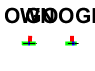

[xhat, meas] = filterTemplate_acc_fusion();

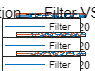

clc
close all
clear all
load meas_task7.mat
load xhat_task7.mat
%%  Plot the euler angles
filter = 180/pi*q2euler(xhat.x);
phone = 180/pi*q2euler(meas.orient);

figure;
sgtitle('Orientation --- Filter VS Phone')
subplot(3,1,1);
plot(xhat.t, filter(1,:))
hold on 
plot(meas.t, phone(1, :))
legend('Filter', 'Phone')
xlabel('time [s]')
ylabel('phi [deg]')

subplot(3,1,2);
plot(xhat.t, filter(2,:))
hold on 
plot(meas.t, phone(2, :))
legend('Filter', 'Phone')
xlabel('time [s]')
ylabel('theta [deg]')

subplot(3,1,3);
plot(xhat.t, filter(3,:))
hold on 
plot(meas.t, phone(3, :))
legend('Filter', 'Phone')
xlabel('time [s]')
ylabel('psi [deg]')

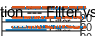

%change the tmin and tmax according to previous figure.
tmin = 0;
tmax = 20;
idx = xhat.t>tmin & xhat.t < tmax;

figure('Color','white','Position',[364   363  1258   473]);
sgtitle('Orientation --- Filter vs Phone')

subplot(3,1,1)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([1 0 0]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([1 0 0]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'phi [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})

subplot(3,1,2)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([0 1 0]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([0 1 0]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'theta [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})


subplot(3,1,3)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([0 0 1]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([0 0 1]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'psi [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})

Task8 acc_fusion_outlier

clc
close all
clear all
startup();

Loading: C:\Users\Weilong Chen\OneDrive - Chalmers\Desktop\Sensor_Project\Sensorfusion smartphone\sensordata.jar


showIP();%If you use virtual machine, situation varies

Available network interfaces
    1.	192.168.1.106 (MediaTek Wi-Fi 6 MT7921 Wireless LAN Card)


********************
* SensorDataReader started on 192.168.1.106:3400
********************
Connection accepted from 192.168.1.100:42716


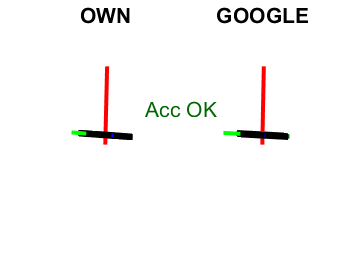

[xhat, meas] = filterTemplate_acc_fusion_outlier();

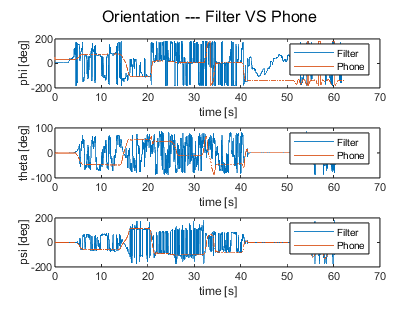

% clc
% close all
% clear all
% load meas_task7.mat
% load xhat_task7.mat
%%  Plot the euler angles
filter = 180/pi*q2euler(xhat.x);
phone = 180/pi*q2euler(meas.orient);

figure;
sgtitle('Orientation --- Filter VS Phone')
subplot(3,1,1);
plot(xhat.t, filter(1,:))
hold on 
plot(meas.t, phone(1, :))
legend('Filter', 'Phone')
xlabel('time [s]')
ylabel('phi [deg]')

subplot(3,1,2);
plot(xhat.t, filter(2,:))
hold on 
plot(meas.t, phone(2, :))
legend('Filter', 'Phone')
xlabel('time [s]')
ylabel('theta [deg]')

subplot(3,1,3);
plot(xhat.t, filter(3,:))
hold on 
plot(meas.t, phone(3, :))
legend('Filter', 'Phone')
xlabel('time [s]')
ylabel('psi [deg]')

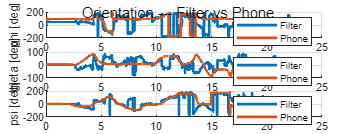

%change the tmin and tmax according to previous figure.
tmin = 0;
tmax = 25;
idx = xhat.t>tmin & xhat.t < tmax;

figure('Color','white','Position',[364   363  1258   473]);
sgtitle('Orientation --- Filter vs Phone')

subplot(3,1,1)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([1 0 0]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([1 0 0]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'phi [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})

subplot(3,1,2)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([0 1 0]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([0 1 0]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'theta [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})


subplot(3,1,3)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([0 0 1]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([0 0 1]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'psi [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})

Task9 see report;

TASK10:

clc
close all
clear all
startup();

Loading: C:\Users\Weilong Chen\OneDrive - Chalmers\Desktop\Sensor_Project\Sensorfusion smartphone\sensordata.jar


showIP();%If you use virtual machine, situation varies

Available network interfaces
    1.	192.168.1.106 (MediaTek Wi-Fi 6 MT7921 Wireless LAN Card)


********************
* SensorDataReader started on 192.168.1.106:3400
********************
Connection accepted from 192.168.1.100:39544


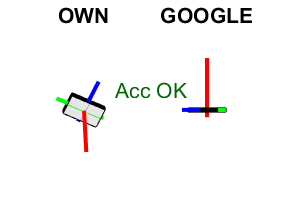

[xhat, meas] = filterTemplate_acc_mag_fusion();

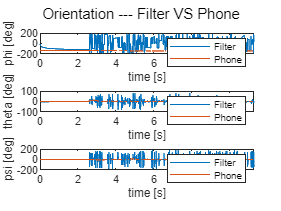

% clc
% close all
% clear all
% load meas_task7.mat
% load xhat_task7.mat
%%  Plot the euler angles
filter = 180/pi*q2euler(xhat.x);
phone = 180/pi*q2euler(meas.orient);

figure;
sgtitle('Orientation --- Filter VS Phone')
subplot(3,1,1);
plot(xhat.t, filter(1,:))
hold on 
plot(meas.t, phone(1, :))
legend('Filter', 'Phone')
xlabel('time [s]')
ylabel('phi [deg]')

subplot(3,1,2);
plot(xhat.t, filter(2,:))
hold on 
plot(meas.t, phone(2, :))
legend('Filter', 'Phone')
xlabel('time [s]')
ylabel('theta [deg]')

subplot(3,1,3);
plot(xhat.t, filter(3,:))
hold on 
plot(meas.t, phone(3, :))
legend('Filter', 'Phone')
xlabel('time [s]')
ylabel('psi [deg]')

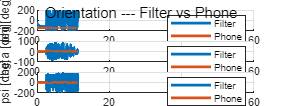

%change the tmin and tmax according to previous figure.
tmin = 0;
tmax = 60;
idx = xhat.t>tmin & xhat.t < tmax;

figure('Color','white','Position',[364   363  1258   473]);
sgtitle('Orientation --- Filter vs Phone')

subplot(3,1,1)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([1 0 0]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([1 0 0]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'phi [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})

subplot(3,1,2)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([0 1 0]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([0 1 0]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'theta [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})


subplot(3,1,3)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([0 0 1]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([0 0 1]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'psi [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})

TASK11:

clc
close all
clear all
startup();

Loading: C:\Users\Weilong Chen\OneDrive - Chalmers\Desktop\Sensor_Project\Sensorfusion smartphone\sensordata.jar


showIP();%If you use virtual machine, situation varies

Available network interfaces
    1.	192.168.1.106 (MediaTek Wi-Fi 6 MT7921 Wireless LAN Card)


********************
* SensorDataReader started on 192.168.1.106:3400
********************
Connection accepted from 192.168.1.100:42524


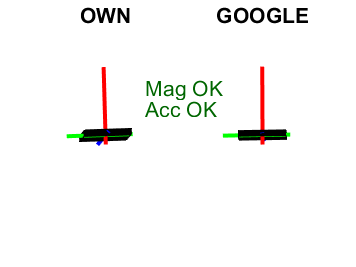

[xhat, meas] = filterTemplate_acc_mag_fusion_outlier();

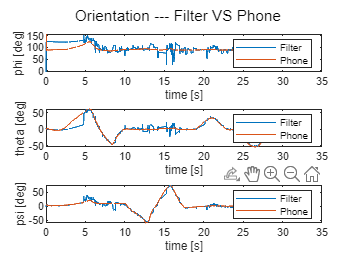

% clc
% close all
% clear all
% load meas_task7.mat
% load xhat_task7.mat
%%  Plot the euler angles
filter = 180/pi*q2euler(xhat.x);
phone = 180/pi*q2euler(meas.orient);

figure;
sgtitle('Orientation --- Filter VS Phone')
subplot(3,1,1);
plot(xhat.t, filter(1,:))
hold on 
plot(meas.t, phone(1, :))
legend('Filter', 'Phone')
xlabel('time [s]')
ylabel('phi [deg]')

subplot(3,1,2);
plot(xhat.t, filter(2,:))
hold on 
plot(meas.t, phone(2, :))
legend('Filter', 'Phone')
xlabel('time [s]')
ylabel('theta [deg]')

subplot(3,1,3);
plot(xhat.t, filter(3,:))
hold on 
plot(meas.t, phone(3, :))
legend('Filter', 'Phone')
xlabel('time [s]')
ylabel('psi [deg]')

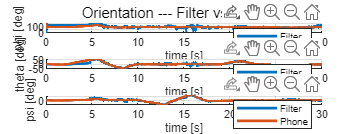

%change the tmin and tmax according to previous figure.
tmin = 0;
tmax = 30;
idx = xhat.t>tmin & xhat.t < tmax;

figure('Color','white','Position',[364   363  1258   473]);
sgtitle('Orientation --- Filter vs Phone')

subplot(3,1,1)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([1 0 0]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([1 0 0]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'phi [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})

subplot(3,1,2)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([0 1 0]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([0 1 0]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'theta [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})


subplot(3,1,3)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([0 0 1]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([0 0 1]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'psi [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})

TASK12:

clc
close all
clear all
startup();

Loading: C:\Users\Weilong Chen\OneDrive - Chalmers\Desktop\Sensor_Project\Sensorfusion smartphone\sensordata.jar


showIP();%If you use virtual machine, situation varies

Available network interfaces
    1.	192.168.1.106 (MediaTek Wi-Fi 6 MT7921 Wireless LAN Card)


********************
* SensorDataReader started on 192.168.1.106:3400
********************
Connection accepted from 192.168.1.100:42652


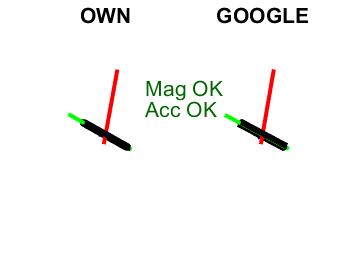

[xhat, meas] = filterTemplate_no_gyro();

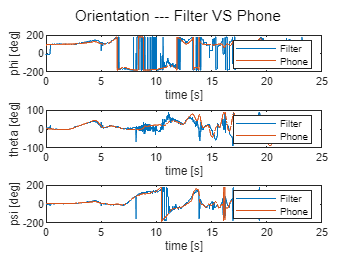

% clc
% close all
% clear all
% load meas_task7.mat
% load xhat_task7.mat
%%  Plot the euler angles
filter = 180/pi*q2euler(xhat.x);
phone = 180/pi*q2euler(meas.orient);

figure;
sgtitle('Orientation --- Filter VS Phone')
subplot(3,1,1);
plot(xhat.t, filter(1,:))
hold on 
plot(meas.t, phone(1, :))
legend('Filter', 'Phone')
xlabel('time [s]')
ylabel('phi [deg]')

subplot(3,1,2);
plot(xhat.t, filter(2,:))
hold on 
plot(meas.t, phone(2, :))
legend('Filter', 'Phone')
xlabel('time [s]')
ylabel('theta [deg]')

subplot(3,1,3);
plot(xhat.t, filter(3,:))
hold on 
plot(meas.t, phone(3, :))
legend('Filter', 'Phone')
xlabel('time [s]')
ylabel('psi [deg]')

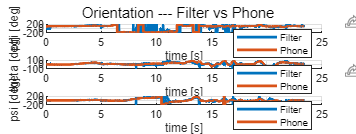

%change the tmin and tmax according to previous figure.
tmin = 0;
tmax = 25;
idx = xhat.t>tmin & xhat.t < tmax;

figure('Color','white','Position',[364   363  1258   473]);
sgtitle('Orientation --- Filter vs Phone')

subplot(3,1,1)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([1 0 0]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([1 0 0]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'phi [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})

subplot(3,1,2)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([0 1 0]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([0 1 0]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'theta [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})


subplot(3,1,3)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([0 0 1]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([0 0 1]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'psi [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})

clc
close all
clear all
startup();

Loading: C:\Users\Weilong Chen\OneDrive - Chalmers\Desktop\Sensor_Project\Sensorfusion smartphone\sensordata.jar


showIP();%If you use virtual machine, situation varies

Available network interfaces
    1.	192.168.1.106 (MediaTek Wi-Fi 6 MT7921 Wireless LAN Card)


********************
* SensorDataReader started on 192.168.1.106:3400
********************
Connection accepted from 192.168.1.100:42824


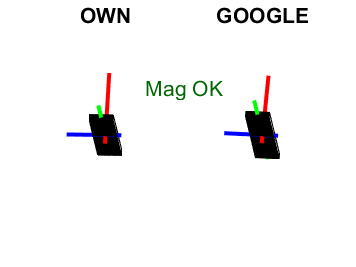

[xhat, meas] = gyro_mag_no_acc();

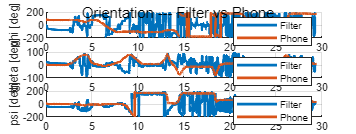

%change the tmin and tmax according to previous figure.
tmin = 0;
tmax = 30;
idx = xhat.t>tmin & xhat.t < tmax;

figure('Color','white','Position',[364   363  1258   473]);
sgtitle('Orientation --- Filter vs Phone')

subplot(3,1,1)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([1 0 0]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([1 0 0]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'phi [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})

subplot(3,1,2)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([0 1 0]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([0 1 0]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'theta [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})


subplot(3,1,3)
hold on; grid on; 
plot(xhat.t(idx)', 180/pi*([0 0 1]*q2euler(xhat.x(:,idx)))',      'LineWidth', 2)
plot(xhat.t(idx)', 180/pi*([0 0 1]*q2euler(meas.orient(:,idx)))', 'LineWidth', 2)
xlim([tmin, tmax])
ylabel 'psi [deg]', xlabel 'time [s]'
legend({'Filter', 'Phone'})